## Question :2

 Logistic Regression. In this problem, you will learn how to implement logistic regression. You are given: i) two different training data sets: P2-data1.txt and P2-data2.txt, and ii) two different validation data sets: P2-valdata1.txt and P2-valdata2.txt. As discussed in the class, the training datasets should be used to train your selected hypothesis classes while the validation datasets should be used to select the most appropriate hypothesis class. For each data set, there are two input variables, x1 and x2, and one output variable, y. In each file, the two inputs are represented by the first two columns, and the output variable is represented by the third column. Assume that the output variable is binary, i.e., y ∈ {0, 1}. For this setup, answer the following questions. In parts (a) and (c) below, please limit your choices to the polynomial hypothesis classes of degree 6 or less. 

(a)  Visualize the training data set in file P2-data1.txt by plotting the labeled data points as a function of the two features. Based on this, select the candidate hypothesis classes (equivalently, models). Train these models using P2-data1.txt. While you used the gradient decent algorithm to obtain the optimal linear regression parameters in Problem 1, you are going to use the fminunc built-in function in MATLAB to train your models in this problem. The function fminunc is an optimization solver that finds the minimum of an unconstrained optimization problem (which is the case for regression problems). For the function fminunc, please use the maximum number of iterations as 400, and initialize all the learning parameters to 0. Plot the decision boundary along with the training data set. 						

clear;close all; clc;
%  Model-1 : B0 + B1X1 + B2X2 


data= load('/Users/parisha/Desktop/AT-ML/ECE6604-MP1/Data sets/Logistic regression/P2-data1.txt');
test_data = load('/Users/parisha/Desktop/AT-ML/ECE6604-MP1/Data sets/Logistic regression/P2-valdata1.txt');

X = [data(:,1) data(:,2) ];
test_X = [test_data(:,1) test_data(:,2) ];
y = data(:,3);
test_y = test_data(:,3);



for i=1:length(y)
    if y(i)== 0
        plot(data(i,1),data(i,2),'r.')
        hold on
        
    else 
        plot(data(i,1),data(i,2),'b+')
        hold on
    end
end
title('Training Dataset P2-data1.txt')
xlabel('X1')
ylabel('X2')


[m, n] = size(X);
[test_m, test_n] = size(test_X);
X = [ones(m, 1) X];
test_X = [ones(test_m, 1) test_X];



initial_Beta = zeros(n + 1, 1);
[cost, grad] = NegLogLike(initial_Beta, X, y);


fprintf('Cost for initial Parameters: %f\n', cost);

Cost for initial Parameters: 0.693147


fprintf('Gradient for Initial Parameters: \n');

Gradient for Initial Parameters: 


fprintf(' %f \n', grad);

 -0.120000 
 -13.391854 
 -12.609769 



%  Set options for fminunc
options = optimset('GradObj', 'on', 'MaxIter', 400);
[Beta, cost] = fminunc(@(t)(NegLogLike(t, X, y)), initial_Beta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


fprintf('Cost for Beta found by fminunc: %f\n', cost);

Cost for Beta found by fminunc: 0.135896


fprintf('Beta: \n');

Beta: 


fprintf(' %f \n', Beta);

 -37.006117 
 0.304137 
 0.302938 



plotDecisionBoundary(data,Beta);
hold on;
xlabel('X1','FontSize',12)
ylabel('X2','FontSize',12)


p = sigmoid(Beta, X);
test_p = sigmoid(Beta, test_X);

fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 91.000000


Model_error = 100 - (mean(double(p == y)) * 100);
fprintf('Model Error : %d Percent\n',Model_error);

Model Error : 9 Percent




fprintf('Test Accuracy: %f\n', mean(double(test_p == test_y)) * 100);

Test Accuracy: 95.000000


test_Model_error = 100 - (mean(double(test_p == test_y)) * 100);
fprintf('Test Error : %f Percent\n',test_Model_error);

Test Error : 5.000000 Percent


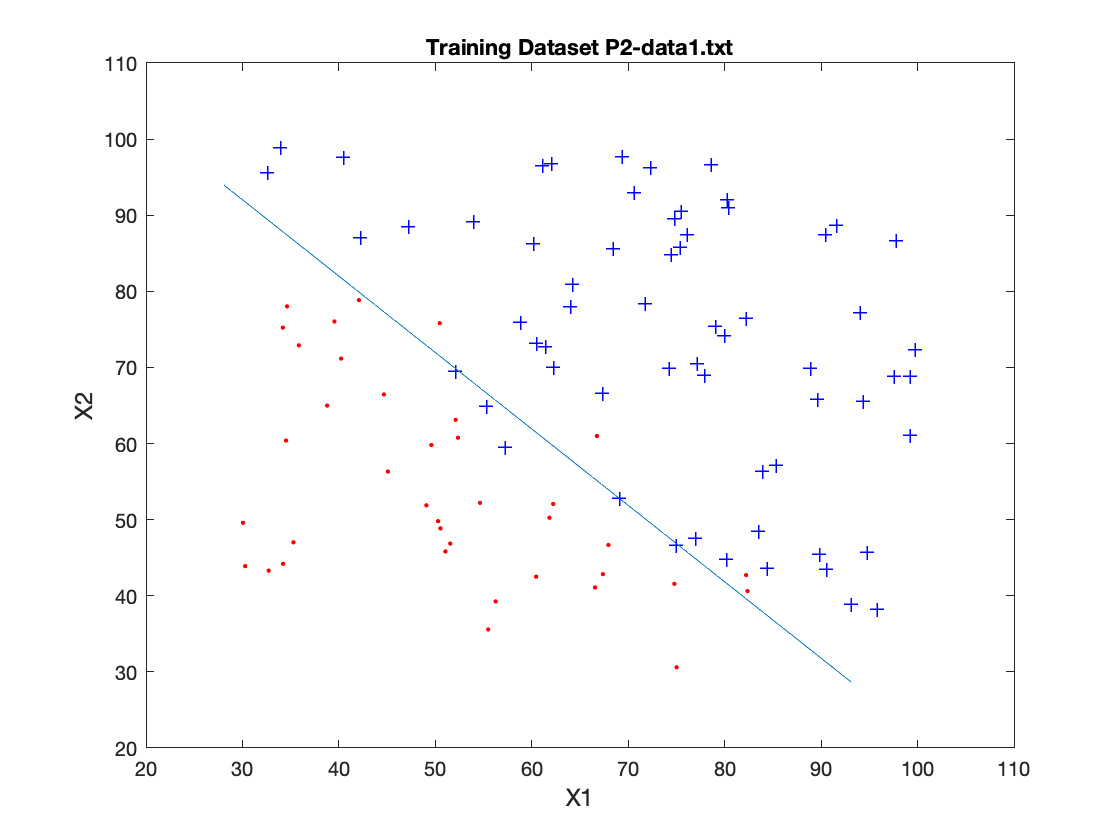

hold off

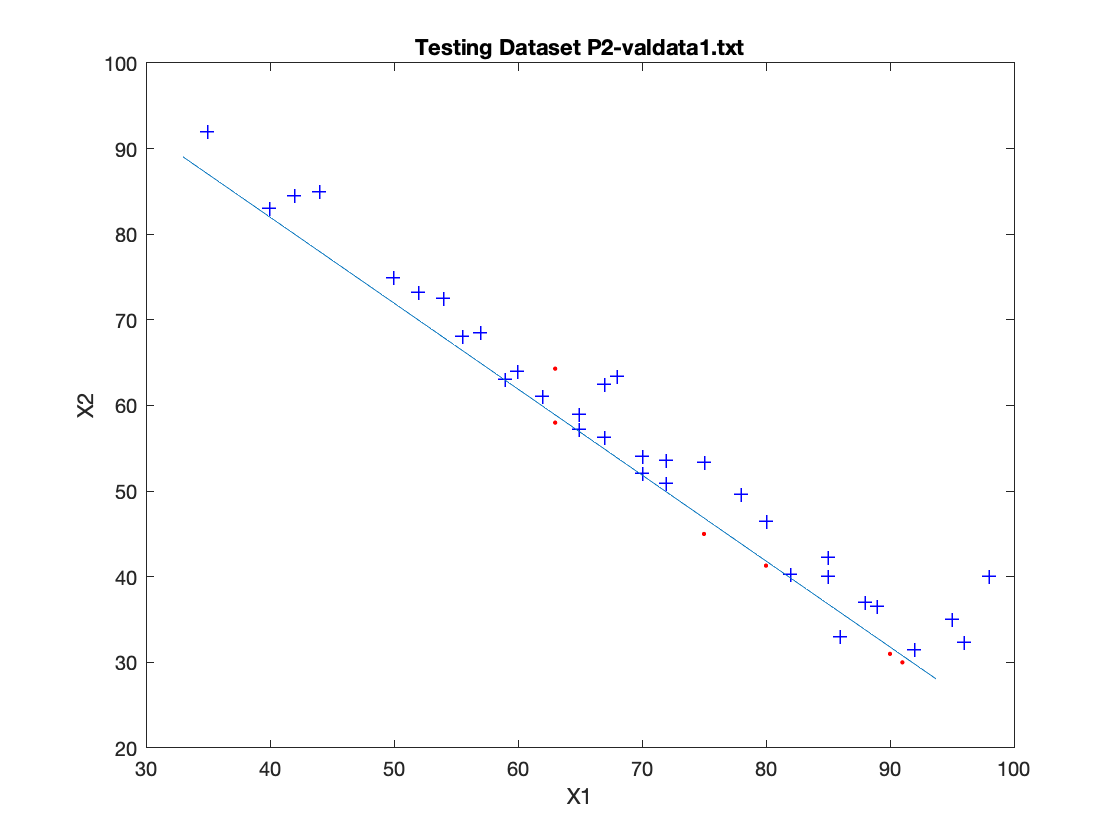

for i=1:length(test_y)
    if test_y(i)== 0
        plot(test_data(i,1),test_data(i,2),'r.')
        hold on
        
    else 
        plot(test_data(i,1),test_data(i,2),'b+')
        hold on
    end
end
title('Testing Dataset P2-valdata1.txt')
xlabel('X1')
ylabel('X2')
plotDecisionBoundary(test_data,Beta);
hold off

function [J, grad] = NegLogLike(Beta, X, y)

m = length(y); 

J=1./m*sum((-y'.*log(1./(1+exp(-Beta'*X'))))-((1-y)'.*log(1-1./(1+exp(-Beta'*X')))));
grad=1./m*(1./(1+exp(-Beta'*X')) -y')*X;


end

function plotDecisionBoundary(data,Beta)
%plot(data(:,1:2), y);
hold on
    x_1 = [min(data(:,1))-2,  max(data(:,1))+2];
    x_2 = [min(data(:,2))-2,  max(data(:,2))+2];
    y_1 = @(x,y) Beta(1)+Beta(2).*x+Beta(3).*y ; 
    fimplicit(y_1,[min(data(:,1))-2 max(data(:,1))+2 min(data(:,2))-2 max(data(:,2))+2]);
hold off
end

function p = sigmoid(Beta, X)

m = size(X, 1); 


p = zeros(m, 1);


for i=1:m
    
    c = -Beta'*X(i,:)';
    p(i) = 1./(1.+exp(c));
    if p(i)>= 0.5
        p(i)=1; 
    else 
        p(i)=0 ;
    end
    
end

end

